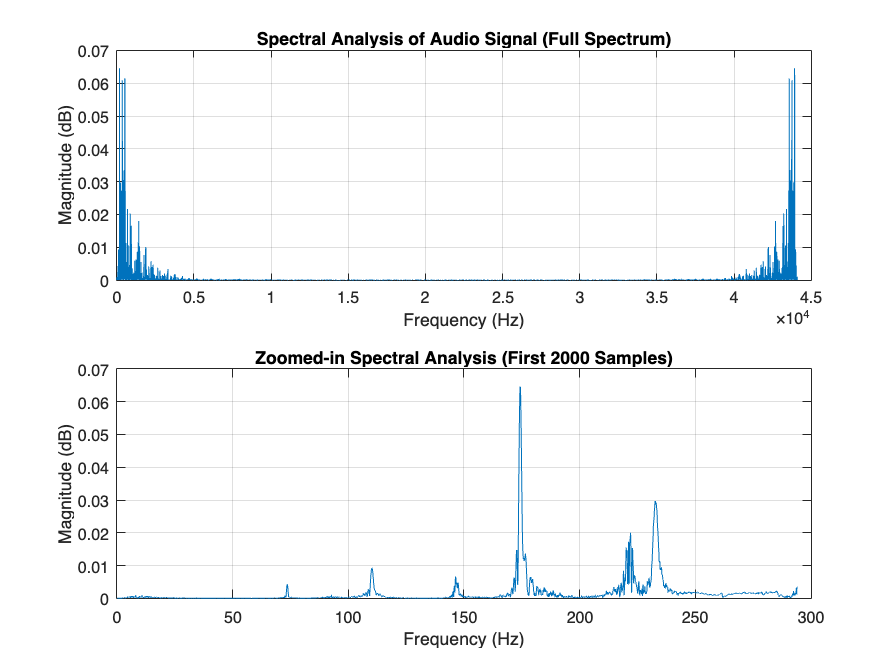

addpath('./lab1');
addpath('./lab2');
% Define the name of the WAV file
file_name = './lab2/musique.wav';
% Use the audioread function to read the WAV file
[audio_data, fs] = audioread(file_name);
% Perform the FFT on the audio data
N = length(audio_data);  % Length of the audio data
% Calculate the one-sided spectrum
[f, audio_spectrum]=transffourier(audio_data,N,fs);
% Plot the entire spectrum
figure;
subplot(2,1,1); % Create a 2x1 grid of plots, select the first subplot
plot(f, abs(audio_spectrum));
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Spectral Analysis of Audio Signal (Full Spectrum)');
grid on;

zoomIn = 2000;
% Zoom in to the first 100 samples
subplot(2,1,2); % Select the second subplot
plot(f(1:zoomIn), abs(audio_spectrum(1:zoomIn)));
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Zoomed-in Spectral Analysis (First 2000 Samples)');
grid on;

Note that an FFT result is mirrored (as in conjugate symmetric) only if the input data is real.

The sampling frequency is 44100
The quantization is 16 bits


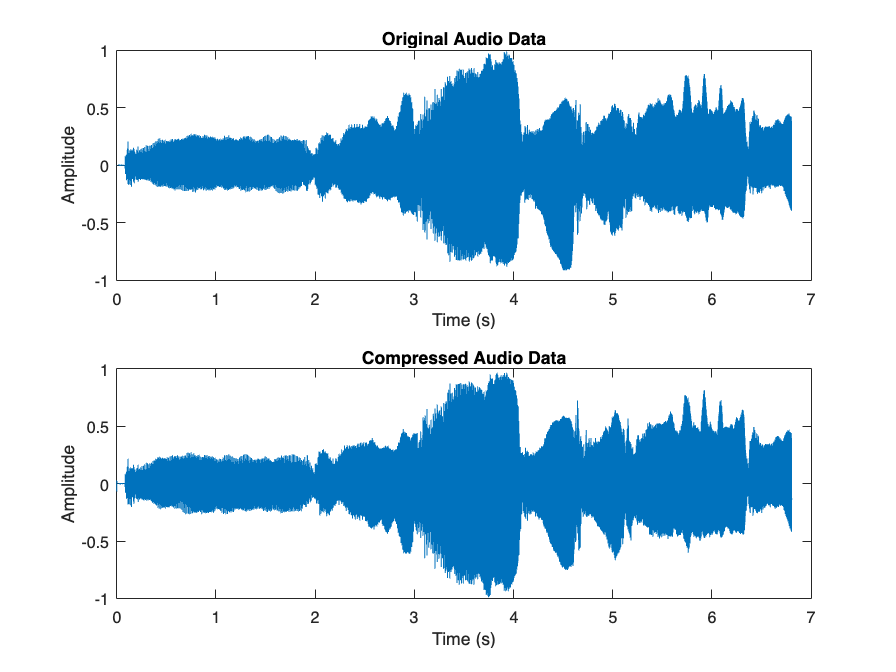

We acchived a compression of 275.5833%
With psnr 8.2662


% Define the name of the WAV file
file_name = './lab2/musique.wav';
fmin = 0;
fmax = 8000;
 
coderDecoder(file_name, fmin, fmax)

The sampling frequency is 44100
The quantization is 16 bits


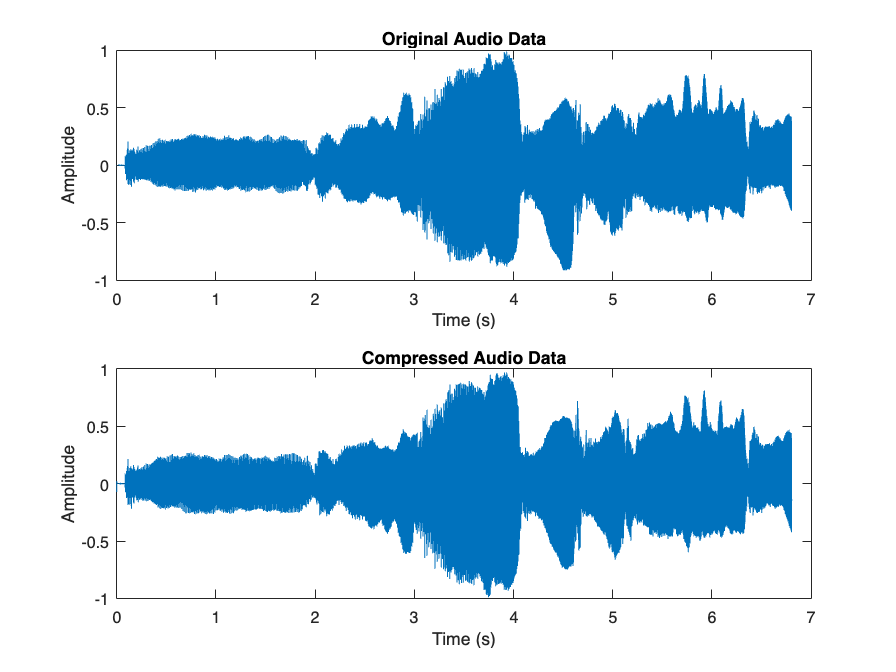

We acchived a compression of 279.0695%
With psnr 8.2767


% Define the name of the WAV file
file_name = './lab2/musique.wav';
fmin = 100;
fmax = 8000;

coderDecoder(file_name, fmin, fmax)

The sampling frequency is 44100
The quantization is 16 bits


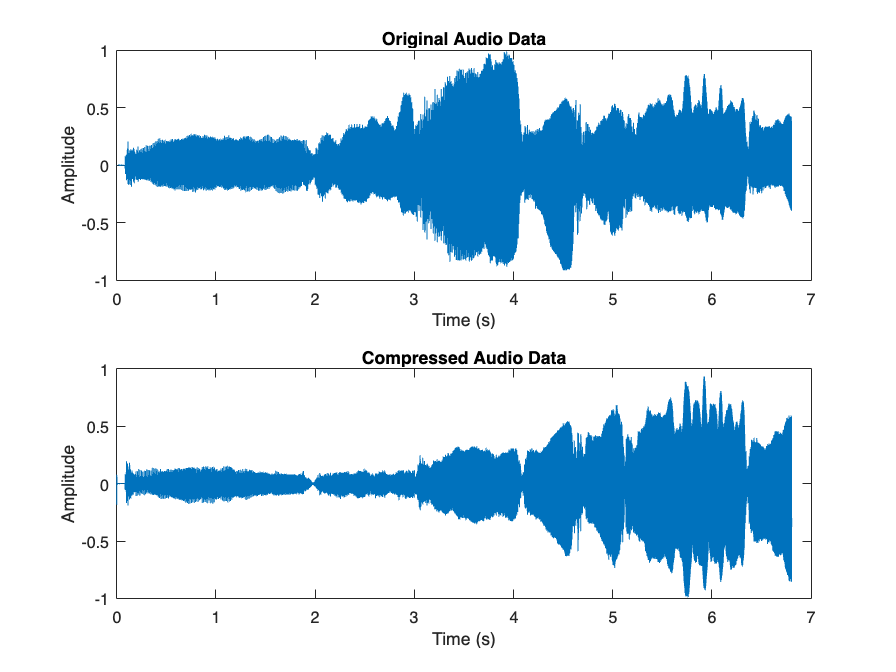

We acchived a compression of 314.944%
With psnr 11.6434


% Define the name of the WAV file
file_name = './lab2/musique.wav';
fmin = 1000;
fmax = 8000;

coderDecoder(file_name, fmin, fmax)

The sampling frequency is 44100
The quantization is 16 bits


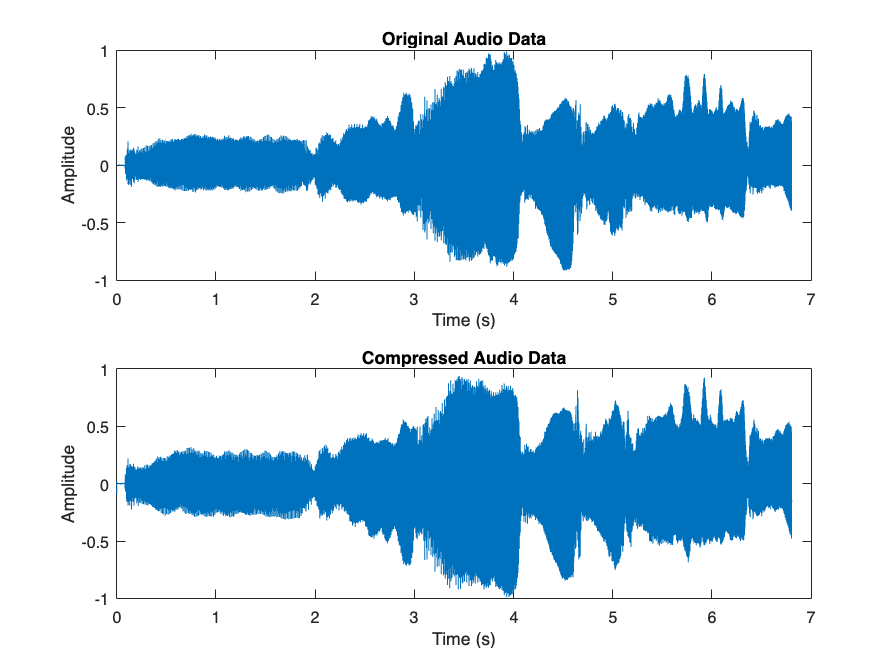

We acchived a compression of 324.2079%
With psnr 8.3968


% Define the name of the WAV file
file_name = './lab2/musique.wav';
fmin = 200;
fmax = 7000;

coderDecoder(file_name, fmin, fmax)